% M. Ffrench 2022 - Radar Data for aUToTrack

% Define the EKF for a single Target and simulate this target over a series
% of trajectories

% trajectories take the form [x_pos; y_pox; time]
% distances are in m and time is in s

rng(42);

steps = 200;
x_lat = 6;
y_head = 0;
f_serpent=1/4;

sim_time = 20;
delta = (sim_time)/steps;

% directly along y i.e. lateral to x
lateral_t = [x_lat*ones(1, steps); linspace(-10, 10, steps); linspace(0, sim_time, steps)]'; 

% directly along x
heading_t = [linspace(0.5, 40, steps); y_head*ones(1, steps); linspace(0, sim_time, steps)]'; 

% Run along x oscillating around y
serpent_t = [linspace(0.5, 40, steps); sin(linspace(0, 2*pi*f_serpent*sim_time, steps)); linspace(0, sim_time, steps)]'; 


% True vel
lat_vel = [zeros(1, steps); ones(steps)]';
head_vel = [1.9751*ones(1, steps); zeros(1, steps)]';
serp_vel = [1.9751*ones(1, steps); 2*pi*f_serpent*cos(linspace(0, sim_time*f_serpent*pi*2, steps))]';

true_traj = lateral_t;
true_vel = lat_vel;

true_state = [true_traj(:, 1:2)  true_vel(:, 1:2)];
measure_traj = true_traj;

% Construct Vrad from True position and Vel
measure_vrad = (measure_traj(:,1).*true_vel(:, 1) + measure_traj(:,2).*true_vel(:, 2))./sqrt(measure_traj(:,1).*measure_traj(:,1) + measure_traj(:,2).*measure_traj(:,2));

% Corrupt position measurements with noise
measure_traj(:, 1) = normrnd(0, 0.15, steps, 1) + measure_traj(:, 1);
measure_traj(:, 2) = normrnd(0, 0.15, steps, 1) + measure_traj(:, 2);
measure_vrad = measure_vrad + normrnd(0, 0.15, size(measure_vrad));

% Consolidate measurements, now has form [x_meas, y_meas, vrad_meas, time]
measure_traj = [measure_traj(:, 1) measure_traj(:, 2) measure_vrad measure_traj(:, 3)];

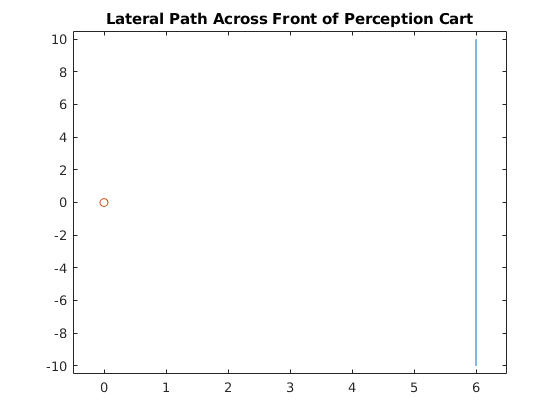

% We only maintain a single track we trust, initialized at first position
% But assume we don't know velocity information

% Process Noise
Q = diag([ 0.015 0.015 0.05 0.05 ]);
P = Q*10;
R = diag([ 0.05 0.05 0.05]);

track_state = [ true_traj(1, 1:2) 0 0 ]';
track_cov = P;

state_estimate = nan(steps, 4);
state_estimate(1, :) = track_state';

% Simulate Tracking
for i = 2:size(measure_traj, 1)
    % Predict
    [x_check, A] = MotionModel(track_state, delta);
    P_check = A*track_cov*(A') + Q;
    
    [measure_state, C] = MeasurementModel(x_check, 3);
    % Kalman Gain
    K = P_check*(C')*inv(C*P_check*(C') + R);
    
    % Correct
    track_cov = (eye(4) - K*C)*P_check;
    track_state = x_check + K*(measure_traj(i, 1:3)' - measure_state);
    
    % Keep history for plotting
    state_estimate(i, :) = track_state'; 
end

% Plotting
close all;
figure;
time = true_traj(:, 3);
plot(true_traj(:,1), true_traj(:,2));
hold on;
scatter([0], [0]);
xlim([-0.5 6.5]);
ylim([-10.5 10.5]);
% hold on;
% plot(state_estimate(:,1), state_estimate(:,2));
% legend("True Path","Tracked Path");
title("Lateral Path Across Front of Perception Cart");

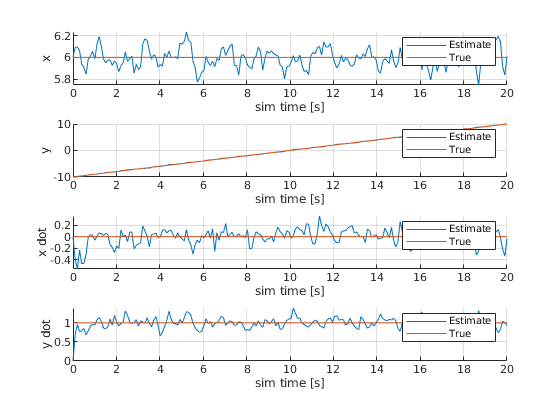


figure;
subplot(4,1,1);
hold on;
grid on;
plot(time, state_estimate(:, 1));
plot(time, true_state(:, 1));
legend("Estimate", "True");
xlabel('sim time [s]');
ylabel('x');
subplot(4,1,2);
hold on;
grid on;
plot(time, state_estimate(:, 2));
plot(time, true_state(:, 2));
legend("Estimate", "True");
xlabel('sim time [s]');
ylabel('y');

subplot(4,1,3);
hold on;
grid on;
plot(time, state_estimate(:, 3));
plot(time, true_state(:, 3));
legend("Estimate", "True");
xlabel('sim time [s]');
ylabel('x dot');

subplot(4,1,4);
hold on;
grid on;
plot(time, state_estimate(:, 4));
plot(time, true_state(:, 4));
legend("Estimate", "True");
xlabel('sim time [s]');
ylabel('y dot');

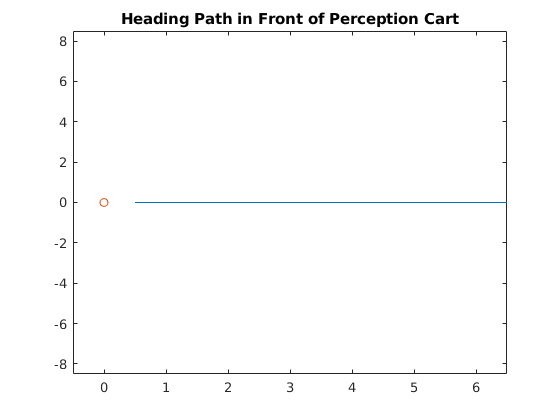

% Heading Path

true_traj = heading_t;
true_vel = head_vel;

true_state = [true_traj(:, 1:2)  true_vel(:, 1:2)];
measure_traj = true_traj;

% Construct Vrad from True position and Vel
measure_vrad = (measure_traj(:,1).*true_vel(:, 1) + measure_traj(:,2).*true_vel(:, 2))./sqrt(measure_traj(:,1).*measure_traj(:,1) + measure_traj(:,2).*measure_traj(:,2));

% Corrupt position measurements with noise
measure_traj(:, 1) = normrnd(0, 0.15, steps, 1) + measure_traj(:, 1);
measure_traj(:, 2) = normrnd(0, 0.15, steps, 1) + measure_traj(:, 2);
measure_vrad = measure_vrad + normrnd(0, 0.15, size(measure_vrad));

% Consolidate measurements, now has form [x_meas, y_meas, vrad_meas, time]
measure_traj = [measure_traj(:, 1) measure_traj(:, 2) measure_vrad measure_traj(:, 3)];

% Process Noise
Q = diag([ 0.015 0.015 0.05 0.05 ]);
P = Q*10;
R = diag([ 0.05 0.05 0.05]);

track_state = [ true_traj(1, 1:2) 0 0 ]';
track_cov = P;

state_estimate = nan(steps, 4);
state_estimate(1, :) = track_state';

% Simulate Tracking
for i = 2:size(measure_traj, 1)
    % Predict
    [x_check, A] = MotionModel(track_state, delta);
    P_check = A*track_cov*(A') + Q;
    
    [measure_state, C] = MeasurementModel(x_check, 3);
    % Kalman Gain
    K = P_check*(C')*inv(C*P_check*(C') + R);
    
    % Correct
    track_cov = (eye(4) - K*C)*P_check;
    track_state = x_check + K*(measure_traj(i, 1:3)' - measure_state);
    
    % Keep history for plotting
    state_estimate(i, :) = track_state'; 
end


% Plotting
close all;
figure;
time = true_traj(:, 3);
plot(true_traj(:,1), true_traj(:,2));
hold on;
scatter([0], [0]);
xlim([-0.5 6.5]);
ylim([-8.5 8.5]);
title("Heading Path in Front of Perception Cart");

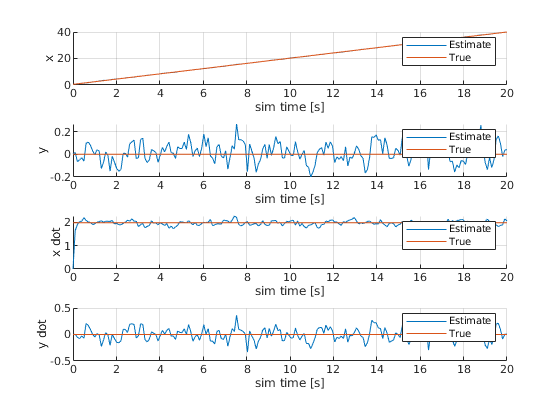


figure;
subplot(4,1,1);
hold on;
grid on;
plot(time, state_estimate(:, 1));
plot(time, true_state(:, 1));
legend("Estimate", "True");
xlabel('sim time [s]');
ylabel('x');
subplot(4,1,2);
hold on;
grid on;
plot(time, state_estimate(:, 2));
plot(time, true_state(:, 2));
legend("Estimate", "True");
xlabel('sim time [s]');
ylabel('y');

subplot(4,1,3);
hold on;
grid on;
plot(time, state_estimate(:, 3));
plot(time, true_state(:, 3));
legend("Estimate", "True");
xlabel('sim time [s]');
ylabel('x dot');

subplot(4,1,4);
hold on;
grid on;
plot(time, state_estimate(:, 4));
plot(time, true_state(:, 4));
legend("Estimate", "True");
xlabel('sim time [s]');
ylabel('y dot');

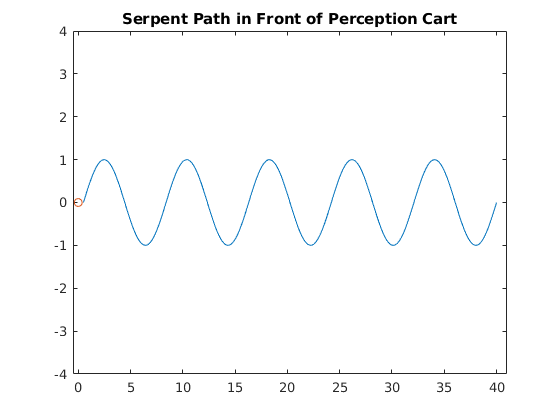

% Serpent Path

true_traj = serpent_t;
true_vel = serp_vel;

true_state = [true_traj(:, 1:2)  true_vel(:, 1:2)];
measure_traj = true_traj;

% Construct Vrad from True position and Vel
measure_vrad = (measure_traj(:,1).*true_vel(:, 1) + measure_traj(:,2).*true_vel(:, 2))./sqrt(measure_traj(:,1).*measure_traj(:,1) + measure_traj(:,2).*measure_traj(:,2));

% Corrupt position measurements with noise
measure_traj(:, 1) = normrnd(0, 0.15, steps, 1) + measure_traj(:, 1);
measure_traj(:, 2) = normrnd(0, 0.15, steps, 1) + measure_traj(:, 2);
measure_vrad = measure_vrad + normrnd(0, 0.15, size(measure_vrad));

% Consolidate measurements, now has form [x_meas, y_meas, vrad_meas, time]
measure_traj = [measure_traj(:, 1) measure_traj(:, 2) measure_vrad measure_traj(:, 3)];

% Process Noise
Q = diag([ 0.015 0.015 0.05 0.05 ]);
P = Q*10;
R = diag([ 0.05 0.05 0.05]);

track_state = [ true_traj(1, 1:2) 0 0 ]';
track_cov = P;

state_estimate = nan(steps, 4);
state_estimate(1, :) = track_state';

% Simulate Tracking
for i = 2:size(measure_traj, 1)
    % Predict
    [x_check, A] = MotionModel(track_state, delta);
    P_check = A*track_cov*(A') + Q;
    
    [measure_state, C] = MeasurementModel(x_check, 3);
    % Kalman Gain
    K = P_check*(C')*inv(C*P_check*(C') + R);
    
    % Correct
    track_cov = (eye(4) - K*C)*P_check;
    track_state = x_check + K*(measure_traj(i, 1:3)' - measure_state);
    
    % Keep history for plotting
    state_estimate(i, :) = track_state'; 
end


% Plotting
close all;
figure;
time = true_traj(:, 3);
plot(true_traj(:,1), true_traj(:,2));
hold on;
scatter([0], [0]);
xlim([-0.5 41]);
ylim([-4 4]);
title("Serpent Path in Front of Perception Cart");

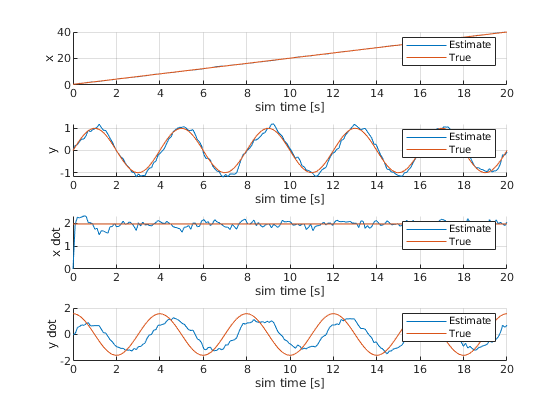


figure;
subplot(4,1,1);
hold on;
grid on;
plot(time, state_estimate(:, 1));
plot(time, true_state(:, 1));
legend("Estimate", "True");
xlabel('sim time [s]');
ylabel('x');
subplot(4,1,2);
hold on;
grid on;
plot(time, state_estimate(:, 2));
plot(time, true_state(:, 2));
legend("Estimate", "True");
xlabel('sim time [s]');
ylabel('y');

subplot(4,1,3);
hold on;
grid on;
plot(time, state_estimate(:, 3));
plot(time, true_state(:, 3));
legend("Estimate", "True");
xlabel('sim time [s]');
ylabel('x dot');

subplot(4,1,4);
hold on;
grid on;
plot(time, state_estimate(:, 4));
plot(time, true_state(:, 4));
legend("Estimate", "True");
xlabel('sim time [s]');
ylabel('y dot');